# 13 Complex Morlet Wavelets and Extracting Power and Phase 

## 13.1 The Wavelet Complex 

To extract power and phase information from EEG data, complex Morlet wavelets are necessary. They are called complex because they have a real part and an imaginary part. A complex wavelet thus occupies a three-dimensional (3-D) space: time, real, and imaginary.

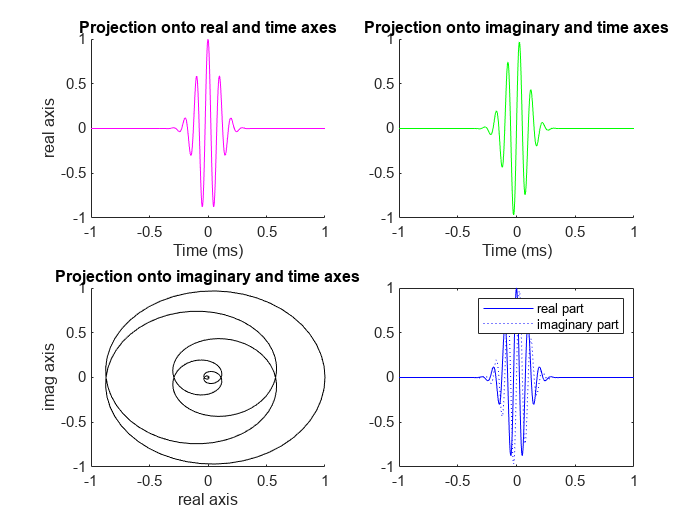

srate = 500;
f     = 10;
time  = -1:1/srate:1;
s     = 6/(2*pi*f);

wavelet = exp(2*pi*1i*f.*time) .* exp(-time.^2./(2*s^2)); 

figure
subplot(221)
plot3(time,real(wavelet),imag(wavelet),'m')
xlabel('Time (ms)'), ylabel('real axis')
view(0,90)
title('Projection onto real and time axes')

subplot(222)
plot3(time,real(wavelet),imag(wavelet),'g')
xlabel('Time (ms)'), ylabel('imaginary axis')
view(0,0)
title('Projection onto imaginary and time axes') 
 
subplot(223)
plot3(time,real(wavelet),imag(wavelet),'k')
ylabel('real axis'), zlabel('imag axis')
view(90,0)
title('Projection onto imaginary and time axes')

subplot(224)
plot(time,real(wavelet),'b')
hold on
plot(time,imag(wavelet),'b:')
legend({'real part';'imaginary part'})

**Figure 13.1 **

*A complex wavelet is a 3-D (time, real, imaginary) function. Plotted here are projections onto various pairs of those dimensions.*

Try to conceptualize wavelets not as curvy lines that go up and down but rather as corkscrews that go around in a circle over time. 

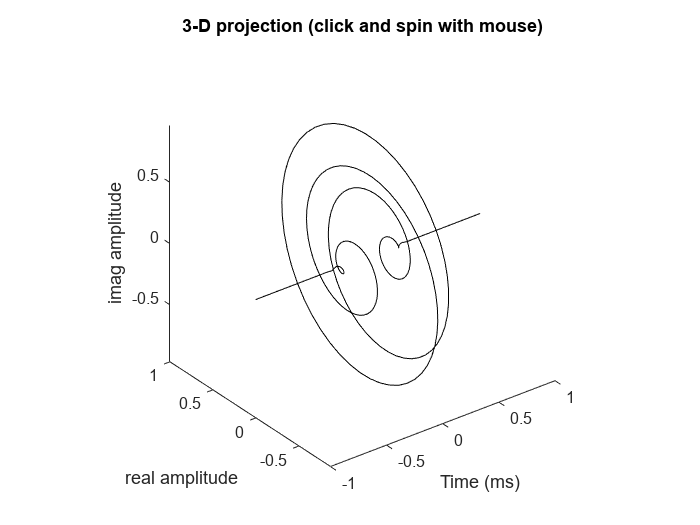

figure
plot3(time,real(wavelet),imag(wavelet),'k')
xlabel('Time (ms)'), ylabel('real amplitude'), zlabel('imag amplitude')
title('3-D projection (click and spin with mouse)')
axis equal
rotate3d

**Figure 13.2 **

*Three-dimensional view of a complex wavelet*

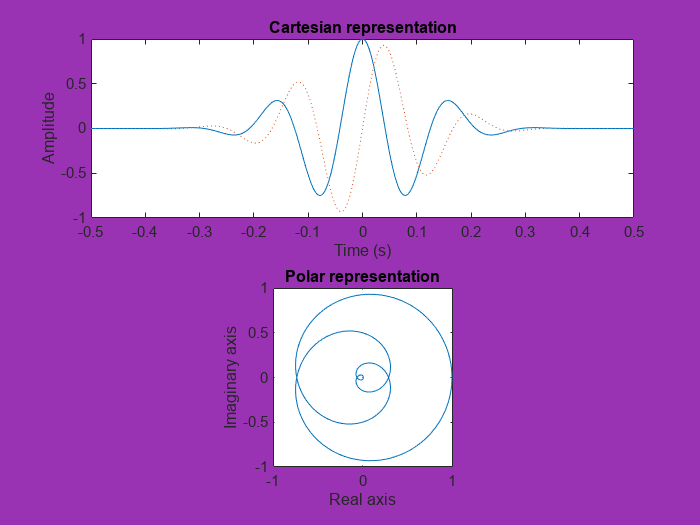

frequency = 6;
srate = 500;
time  = -.5:1/srate:.5;
 
wavelet = exp(2*1i*pi*frequency.*time) .* exp(-time.^2./(2*(4/(2*pi*frequency))^2));

figure, set(gcf,'color',[.6 .2 .7])

timeskip = 1;

subplot(211)
cplotR = plot(time(1),real(wavelet(1)));
hold on
cplotI = plot(time(1),imag(wavelet(1)),':');
set(gca,'ylim',[-1 1],'xlim',[time(1) time(end)])
xlabel('Time (s)'), ylabel('Amplitude')
title('Cartesian representation')

subplot(212)
pplot = plot(real(wavelet(1)),imag(wavelet(1)));
set(gca,'ylim',[-1 1],'xlim',[-1 1])
title('Polar representation')
xlabel('Real axis'), ylabel('Imaginary axis')
axis square
 
for ti=1:timeskip:length(time)
    
    set(cplotR,'XData',time(1:ti),'YData',real(wavelet(1:ti)))
    set(cplotI,'XData',time(1:ti),'YData',imag(wavelet(1:ti)))
    set(pplot,'XData',real(wavelet(1:ti)),'YData',imag(wavelet(1:ti)))
    drawnow
end

**Figure 13.3**

*Cartesian and the polar representations of a complex wavelet evolving over time.*

A complex number has the form “$a+\textrm{ib}$.” The first part of the number ($a$) is the real component, and the second part of the number ($b$) is the imaginary component. The $i$ is the imaginary operator; multiplying a number by $i$ makes that number imaginary.

## 13.2 Imagining the Imaginary 

The imaginary number is the square root of $-1$. That is, a number multiplied by itself that gives you $-1$. Do not worry too much about the interpretation of an imaginary number per se; try to focus on how imaginary numbers are used to extract power and phase information from EEG data. 

The imaginary number is indicated with an $i$ or a $j$. Mathematicians tend to use $i$ and engineers tend to use $j$ to differentiate it from current. Matlab accepts both. Matlab also accepts `1i` and `1j`, which allows you to use $i$ and $j$ as looping indices or other variables. 

## 13.3 Rectangular and Polar Notation and the Complex Plane 

Polar notation is a mathematical framework that is useful for characterizing circular and spherical data. For EEG data analyses, polar notation provides a convenient and succinct language to describe properties of frequency-band-specific activity, including the bandpassfiltered signal, power, and phase. 

Rectangular notation (also called Cartesian notation) is described by x and y coordinates. Consider a complex number as a location on a 2-D plane, except that this plane comprises a real axis and an imaginary axis instead of an x-axis and a y-axis. The two parts of the complex number tell you where that point is on the plane.

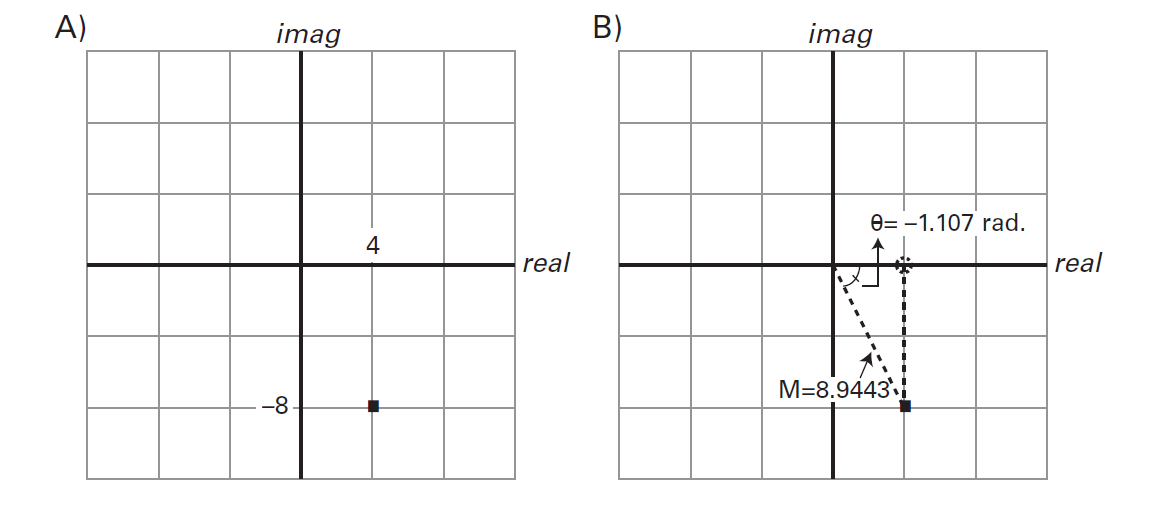

**Figure 13.4**

*The same point in a complex space (with a real axis and an imaginary axis) can be represented using Cartesian (A) or polar (B) notations.*

Converting between rectangular and polar notations is straightforward

The following equations can be used to obtain the magnitude and angle in polar notation when you already have the rectangular notation. 

### 
$$M=\sqrt{\left({\textrm{real}}^2 +{\textrm{imag}}^2 \right)}$$


### 
$$\theta =\arctan \left(\textrm{imag}/\textrm{real}\right)$$


- $\textrm{real}$ is the real component of the complex number

- $\textrm{imag}$ is the imaginary component of the complex number

The magnitude can never be less than zero. The two components (real and imaginary) are squared, and the sum of squared numbers cannot be negative. the length of a line from zero to any point cannot be negative, even when the points themselves have negative coordinates. 

The Matlab function `atan` computes the arctangent and has an exception for when the real part (the denominator) is zero, which prevents $\theta$ from being infinity.

You can also obtain the real and imaginary parts in rectangular notation when you already have the polar notation.

### 
$$\textrm{real}=M\;\cos \left(\theta \right)$$


### 
$$\textrm{imag}=M\;\sin \left(\theta \right)$$


You can see that the real part of a complex number corresponds to a cosine, and the imaginary part of a complex number corresponds to a sine. In the following equations the individual components shown in above equations are combined and then reorganized using algebra, showing how to convert a complex number between the rectangular and polar notations.

### 
$$\textrm{real}+\textrm{imag}=M\;\cos \left(\theta \right)+M\;\sin \left(\theta \right)$$


### 
$$\textrm{real}+\textrm{imag}=M\left\lbrack \cos \left(\theta \right)+\sin \left(\theta \right)\right\rbrack$$


### 
$$a+\textrm{ib}=M\left\lbrack \cos \left(\theta \right)+i\;\sin \left(\theta \right)\right\rbrack$$


## 13.4 Euler’s Formula 

In addition to the Fourier theorem, Euler’s formula is an important tool for time-frequency decomposition that forms the backbone of many advanced EEG data analysis techniques. Euler’s formula allows you to represent complex numbers as points on a circle. The formula follows from the polar notation of a complex number: 

### 
$${\textrm{Me}}^{i\theta } =M\left\lbrack \cos \left(\theta \right)+i\;\sin \left(\theta \right)\right\rbrack$$


- $\theta$ is any real number

- $e$ is the base of the natural logarithm. It is a constant that begins 2.71828. . . . The Matlab function `exp` computes the exponential of the input

You can see that ${\textrm{Me}}^{i\theta }$ is a convenient notation for representing a point in a complex plane and thus can also be used to represent a vector in a complex plane defined by the origin and that point. $M$ is the magnitude of that vector, and $\theta$ is its angle.

It is worth demonstrating that the two sides of the equation are equal. By writing a Matlab code to plot circles using both trigonometric and Euler notation, you can see that modifying the cosine component affects the position along the real axis, while changing the sine component affects the position along the imaginary axis.

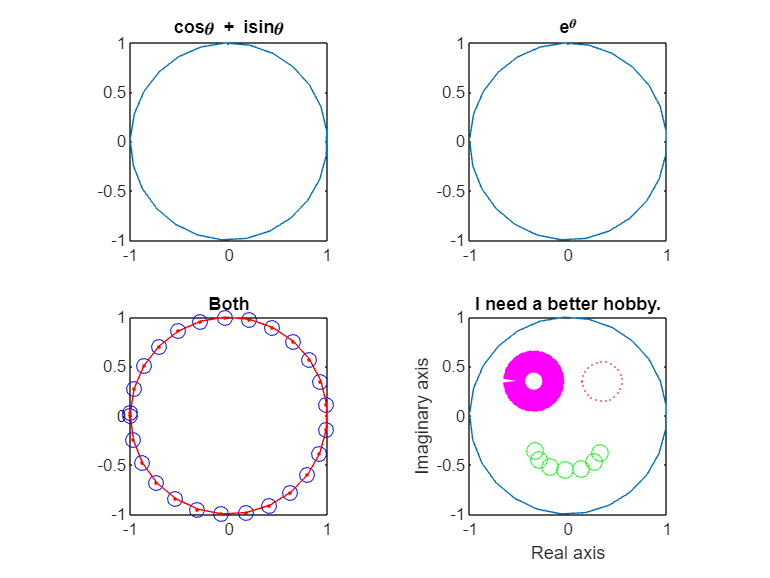

time = -pi:.25:pi;

figure
subplot(221)
plot(cos(time)+1i*sin(time))
axis square
title('cos\theta + isin\theta')
 
subplot(222)
plot(exp(1i*time))
axis square
title('e^i^\theta')
 
subplot(223)
plot(cos(time)+1i*sin(time),'bo-','markersize',8)
hold on
plot(exp(1i*time),'r.-')
axis square
title('Both')
 
subplot(224)
plot(cos(time)+1i*sin(time))
hold on
plot( (-.35+cos(time)/5) + 1i*(.35+sin(time)/5) ,'m','linew',12)
plot( (+.35+cos(time)/5) + 1i*(.35+sin(time)/5) ,'r.','markersize',3)
smile=-pi:.5:0;
plot( (cos(smile)/3) + 1i*(-.35+sin(smile)/5) ,'go','markersize',9)
xlabel('Real axis')
ylabel('Imaginary axis')
axis square
title('I need a better hobby.')

**Figure 13.5**

*Illustration of equality of Euler and trigonometric representations and another illustration (lower right panel) of how the real component corresponds to cosine while the imaginary component corresponds to sine.*

If you look at the imaginary part of the wavelet, you will notice that it looks a bit lopsided. This is because the real part of the wavelet corresponds to a cosine wave, and the imaginary part of the wavelet corresponds to sine wave. The difference between cosine and sine is one-quarter of a cycle, or $\pi /2$.

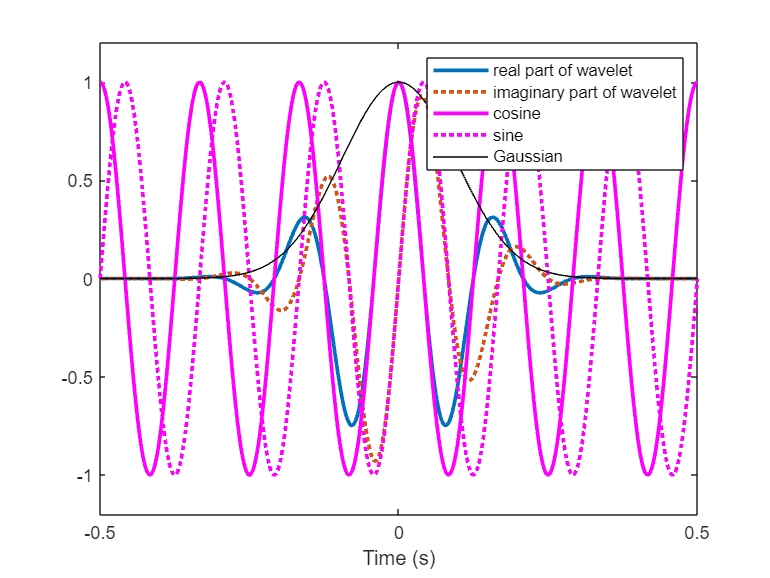

time = -.5:1/srate:.5;

figure

plot(time,real(wavelet),'linew',2)
hold on
plot(time,imag(wavelet),':','linew',2)

plot(time,cos(2*pi*frequency.*time),'m','linew',2)
plot(time,sin(2*pi*frequency.*time),'m:','linew',2)

gaus_win = exp(-time.^2./(2*s^2));
plot(time,gaus_win,'k')
set(gca,'ylim',[-1.2 1.2])
xlabel('Time (s)')
legend({'real part of wavelet';'imaginary part of wavelet';'cosine';'sine';'Gaussian'})

**Figure 13.6**

*Overlaying the real and imaginary parts of a complex wavelet along with a cosine wave and a sine wave. This shows that the real part of the wavelet corresponds to a cosine wave, and the imaginary part of the wavelet corresponds to a sine wave.*

Remember that a real-valued Morlet wavelet is created by multiplying a sine wave by a Gaussian; a complex Morlet wavelet (cmw) is created in the same way, except that the sine wave is a complex sine wave. 

### 
$$\textrm{cmv}={\textrm{Ae}}^{-t^2 /2s^2 } e^{\textrm{i2}\pi \textrm{ft}}$$


### 
$$A=\frac{1}{{\left(s\sqrt{\pi }\right)}^{1/2} }$$


- $t$ is time

- $s$ is the standard deviation of the Gaussian

- $f$ is the peak frequency of the wavelet

- $A$ is a frequency band-specific scaling factor

The first part of equation is a Gaussian. The second part of the equation is a complex sine wave which is formed by combining Euler ’ s formula and the $2\pi \textrm{ft}$ part of a sine wave. If you plan to apply a baseline normalization such as percentage change or decibel, scaling factor is not necessary. Furthermore, if you are performing complex wavelet convolution only to obtain the phase angle time series, the scaling factor is also not necessary.

The formula for the discrete Fourier transform contains Euler’s formula. Thus, to perform a Fourier transform, a dot product is computed between the time series data and a complex sine wave.

## 13.5 Euler ’ s Formula and the Result of Complex Wavelet Convolution 

The dot product between a wavelet and a one-cycle sine wave could be negative, positive, or zero, depending on slight shifts in relative phase between the signal and the kernel.

When you compute the dot product between a complex wavelet and a signal, the result of the dot product is a complex number; it contains both a real part and an imaginary part because the complex wavelet has a real part and an imaginary part. Euler’s formula can be applied to represent that complex number as a point in polar space, and that point can be further conceptualized as the endpoint of a vector from the origin of the polar space to that point.

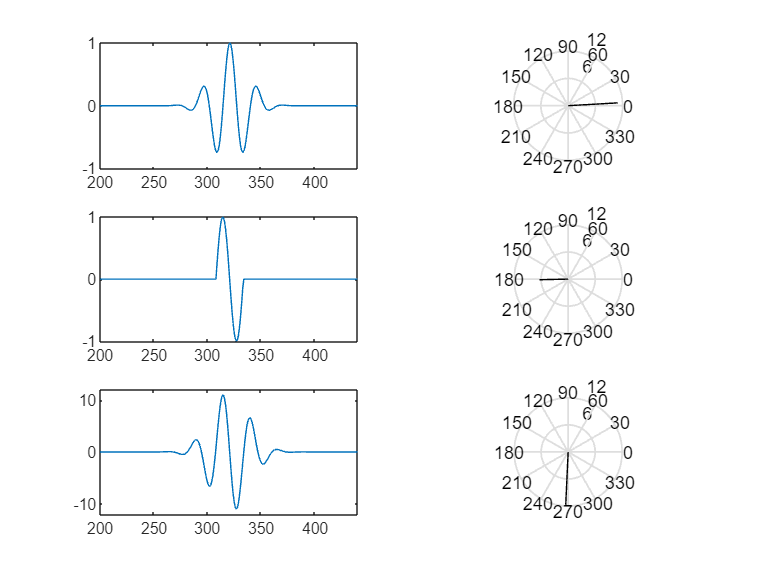

load sampleEEGdata

time = -EEG.pnts/EEG.srate/2 : 1/EEG.srate : EEG.pnts/EEG.srate/2-1/EEG.srate;
f    = 10;
s    = 4/(2*pi*f);
wavelet = exp(1i*2*pi*f.*time) .* exp(-time.^2./(2*s^2));

timeS  = 0:1/EEG.srate:(1/f);
signal = sin(2*pi*f.*timeS);
signal = [ zeros(1,EEG.pnts/2-length(timeS)/2) signal zeros(1,EEG.pnts/2-length(timeS)/2) ];

figure

subplot(321)
plot(real(wavelet))
set(gca,'xlim',[200 length(time)-200])

subplot(323)
plot(signal)
set(gca,'xlim',[200 length(time)-200])

subplot(325)
plot(real(conv(wavelet,signal,'same')))
set(gca,'xlim',[200 length(time)-200],'ylim',[-12 12])

subplot(322)
polar(0,12,'-k'), hold on
dp = sum(wavelet(round(100/f)-2:end).*signal(1:end-round(100/f)+3));
polar([angle(dp) angle(dp)],[0 abs(dp)],'k')

subplot(324)
polar(0,12,'-k'), hold on
dp = sum(wavelet(round(2.3*(100/f)-2):end).*signal(1:end-round(2.3*(100/f)-3)));
polar([angle(dp) angle(dp)],[0 abs(dp)],'k')

subplot(326)
polar(0,12,'-k'), hold on
dp = sum(wavelet.*signal);
polar([angle(dp) angle(dp)],[0 abs(dp)],'k')

**Figure 13.7**

*The dot product between a complex Morlet wavelet (real part shown here using a dotted line) and a one-cycle sine wave produces a complex number, here represented as a vector in a polar plot using the magnitude and angle.*

The result of dot products with the real valued wavelet maps onto the real axis in the result of dot products with complex wavelets; the imaginary axis is ignored in the dot product with the real-valued wavelet.

One final feature to notice is that the more the wavelet and the one-cycle sine wave overlap, the longer is the line in complex space. The length of the line provides information regarding the similarity or overlap between the kernel and the signal. Importantly, the length of this line does not depend on the phase relationship between the kernel and the signal. In contrast, the phase relationship between the kernel and the signal is characterized by the angle of the vector. 

There are three pieces of information that can be extracted from the complex dot product: 

- The projection onto the real axis is the bandpass-filtered signal. This value can be positive or negative, depending on the phase relationship between the kernel and the signal.

- The length (magnitude) of the vector from the origin to the point in complex space is related to the similarity or overlap between the kernel and the signal. The length of this vector is called the amplitude, and the length squared is called the power. This is the estimate of the instantaneous power at the point in time corresponding to the center of the kernal with respect to the signal, and at the peak frequency of the kernal.

- The angle of that vector with respect to the positive real axis is an estimate of the phase angle at the point in time corresponding to the center of the kernal and at the peak frequency of the kernal. 

Note that the power and phase values are called estimates because they are influenced by activity at neighboring time points.

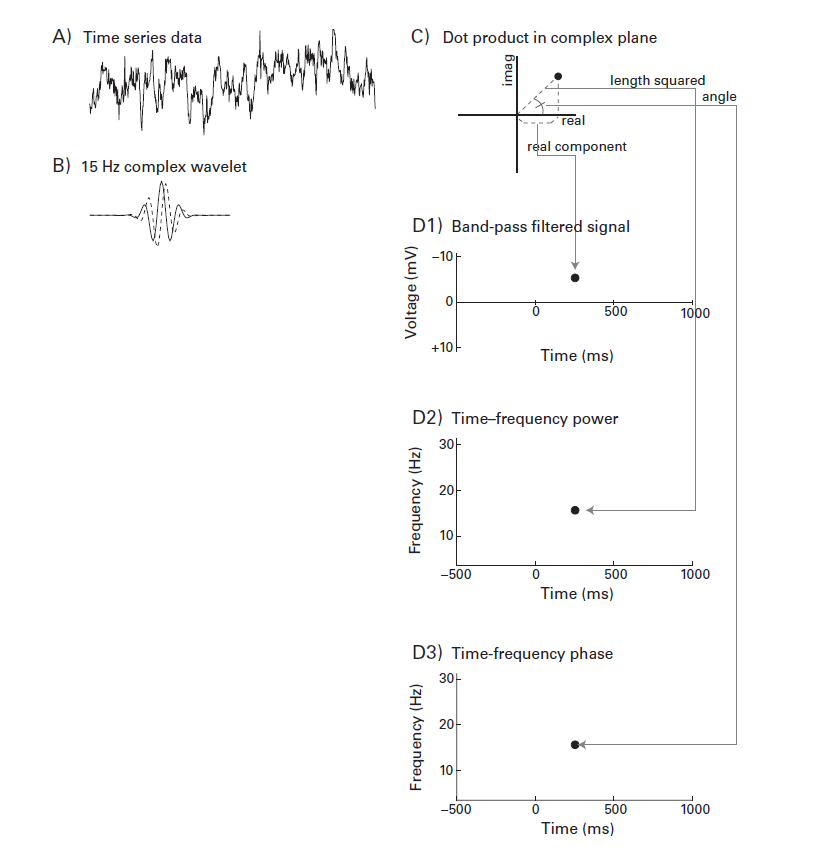

**Figure 13.8**

*Graphical overview of how to extract the bandpass-filtered signal, power, and phase from one step of the result of complex convolution. Each step of convolution between the time series data (panel A) and a complex wavelet (panel B) is a dot product, which can be conceptualized as a point in a complex plane (panel C).*

A brief aside on computational efficiency: power can be extracted either by squaring the length of the complex vector [in Matlab: `abs(X).^2`] or by multiplying the complex vector by its conjugate [in Matlab: `X.*conj(X)`]. The conjugate of a complex number is obtained by multiplying the imaginary part by minus one. Thus, the conjugate of $a+\textrm{ib}$ is $a-\textrm{ib}$ . For large matrices, multiplying the complex vector by its conjugate is faster (around twice as fast, depending on the size of the matrix) and thus should be used in practice with real data.

## 13.6 From Time Point to Time Series

Remember that time-domain convolution involves computing time-sliding dot products between the kernel and the signal. Consider that when the $M$ and $\theta$ in Euler’ s formula can vary over time ($M_t \;e^{i\theta_t }$), you can represent a complex sine wave as spiraling through a circle on a complex plane over time, similar to how the complex wavelet was like a corkscrew over time. And by extracting the magnitude and phase angle of the result of convolution, you can construct a time series of power or phase values from one frequency band. This process would then be repeated over multiple frequency bands to obtain a time-frequency map.

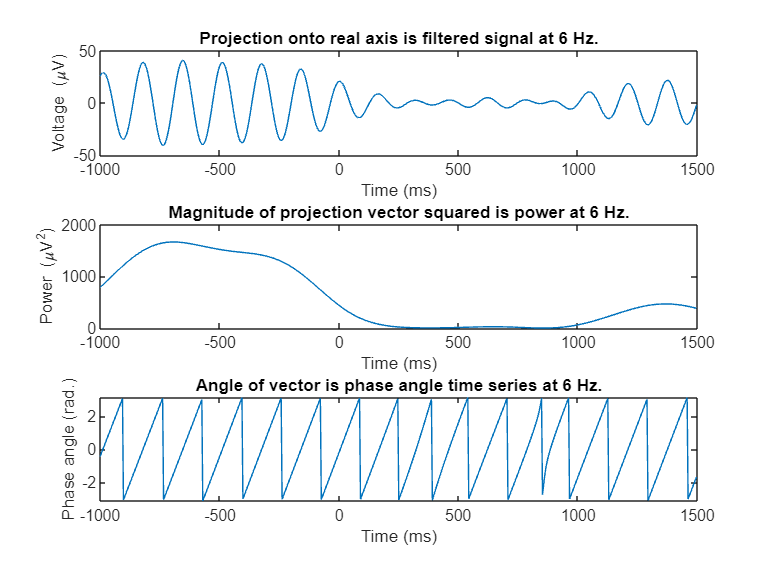

frequency = 6;
time = -1:1/EEG.srate:1;
s    = (4/(2*pi*frequency))^2;
wavelet = exp(2*1i*pi*frequency.*time) .* exp(-time.^2./(2*s)/frequency);

n_wavelet            = length(wavelet);
n_data               = EEG.pnts;
n_convolution        = n_wavelet+n_data-1;
half_of_wavelet_size = (length(wavelet)-1)/2;

fft_wavelet = fft(wavelet,n_convolution);
fft_data    = fft(squeeze(EEG.data(47,:,1)),n_convolution);

convolution_result_fft = ifft(fft_wavelet.*fft_data,n_convolution) * sqrt(s);

convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);

figure
subplot(311)
plot(EEG.times,real(convolution_result_fft))
xlabel('Time (ms)'), ylabel('Voltage (\muV)')
title([ 'Projection onto real axis is filtered signal at ' num2str(frequency) ' Hz.' ])

subplot(312)
plot(EEG.times,abs(convolution_result_fft).^2)
xlabel('Time (ms)'), ylabel('Power (\muV^2)')
title([ 'Magnitude of projection vector squared is power at ' num2str(frequency) ' Hz.' ])

subplot(313)
plot(EEG.times,angle(convolution_result_fft))
xlabel('Time (ms)'), ylabel('Phase angle (rad.)')
title([ 'Angle of vector is phase angle time series at ' num2str(frequency) ' Hz.' ])

**Figure 13.9**

*Different pieces of frequency-band-specific information extracted from EEG via complex wavelet convolution.*

A complex Morlet wavelet is like a corkscrew over time, real, and imaginary axes. You can conceptualize the result of complex wavelet convolution the same way — existing in three dimensions of time, real, and imaginary.

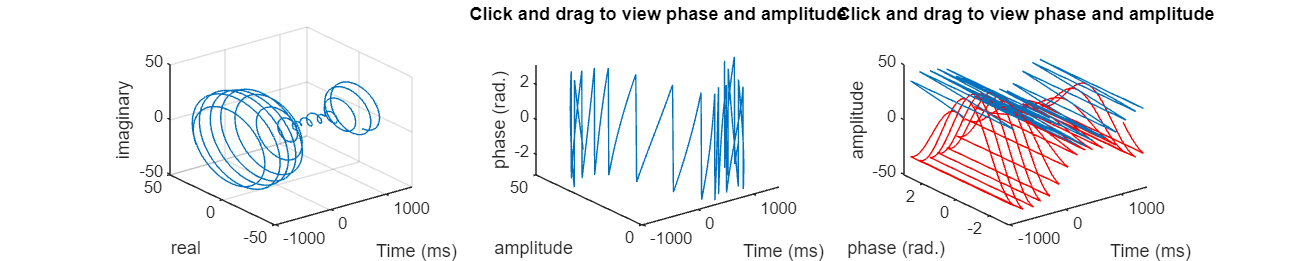

figure(Position=[100,100,1000,200])

subplot(131)
plot3(EEG.times,real(convolution_result_fft),imag(convolution_result_fft))
xlabel('Time (ms)'), ylabel('real'), zlabel('imaginary')
grid on
rotate3d
subplot(132)
plot3(EEG.times,abs(convolution_result_fft),angle(convolution_result_fft))
title('Click and drag to view phase and amplitude')
xlabel('Time (ms)'), ylabel('amplitude'), zlabel('phase (rad.)')
rotate3d
subplot(133)
plot3(EEG.times,angle(convolution_result_fft),abs(convolution_result_fft))
hold on
plot3(EEG.times,angle(convolution_result_fft),real(convolution_result_fft),'r')
title('Click and drag to view phase and amplitude')
xlabel('Time (ms)'), zlabel('amplitude'), ylabel('phase (rad.)')
rotate3d

**Figure 13.10**

*Try to conceptualize the result of complex Morlet wavelet convolution as a line in a 3-D space.*

The result of convolution can then be transformed to a new set of axes. Rather than time, real, and imaginary axes, you can represent the result of convolution in time, amplitude, and phase axes. The seemingly large discrete jumps on the phase axis are due to discontinuous borders in the plot between $-\pi$ and $+\pi$.

## 13.7 Parameters of Wavelets and Recommended Settings

Now that you know how to create and use complex Morlet wavelets, it is time to discuss parameters of wavelets and the consequences those parameters will have on your results. Some of the parameters discussed below are also applicable to other time-frequency decomposition methods such as the filter-Hilbert method.

### 13.7.1 How Low Should the Lowest Frequency Be?

The lowest frequency depends on: 

- Your expectations about the results (If your study is hypothesis-driven and concerns only alpha-band activity, you could probably stop at, say, 5 or 6 Hz)

- Task design 

- Timing of trial events

- Length of your data epochs (you should have at least several cycles worth of time to extract robust band-specific information)

### 13.7.2 How High Should the Highest Frequency Be?

The highest frequency depends on:

- Your expectations about the results (having additional frequencies that are not of interest will lead to more stringent statistical significance thresholding when correcting for multiple comparisons)

- Sampling rate (you cannot examine frequencies higher than the Nyquist frequency, and in practice, it is good to have many data points per cycle to increase signal-to-noise ratio)

If you do not have specific expectations about the frequency band of the results, you could use a range of 4 Hz to 60 Hz. This range is likely to capture the main time-frequency dynamics in most cognitive tasks. If you see task-related activity close to the lowest or highest frequencies, you could reanalyze the data using a broader frequency range.

### 13.7.3 How Many Frequencies Should Be Used?

Having more frequencies gives you:

- Safe zone (there might be individual differences in the exact frequency of the interested peak frequency)

- The freedom to select the appropriate frequency ranges based on the data

- The ability to perform exploratory and post-hoc analyses in addition to the hypothesis based analyses

- Thr ability to produce smoother time-frequency plots that are easier to inspect visually

On the other hand, more frequencies means:

- Larger results matrices

- Increased computation time

- Increased requirements for multiple comparisons corrections

Furthermore, because of frequency smoothing inherent in wavelet convolution, there is autocorrelation in the time-frequency plots. meaning that wavelets with close frequencies will extract similar (although not identical) time-frequency information from EEG data.

In general, 20 – 30 frequencies provide a reasonable number to cover a broad frequency range (e.g., 4 – 60 Hz) while also making nice-looking plots.

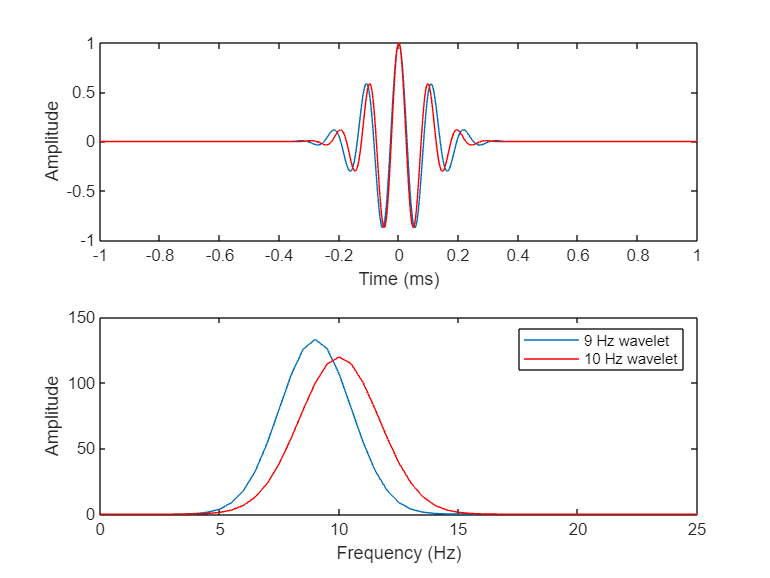

srate = 500;
time  = -1:1/srate:1;

f = 9;
s = 6/(2*pi*f);
wavelet9 = exp(2*pi*1i*f.*time) .* exp(-time.^2./(2*s^2)); 

f = 10;
s = 6/(2*pi*f);
wavelet10 = exp(2*pi*1i*f.*time) .* exp(-time.^2./(2*s^2)); 

figure
subplot(211)
plot(time,real(wavelet9))
hold on
plot(time,real(wavelet10),'r')
xlabel('Time (ms)'), ylabel('Amplitude')

subplot(212)
hz = linspace(0,srate/2,floor(length(time)/2)+1);
fft9  = fft(wavelet9);
fft10 = fft(wavelet10);

plot(hz,abs(fft9(1:length(hz))))
hold on
plot(hz,abs(fft10(1:length(hz))),'r')
set(gca,'xlim',[0 25])
xlabel('Frequency (Hz)'), ylabel('Amplitude')
legend({'9 Hz wavelet';'10 Hz wavelet'})

**Figure 13.11**

*Time-domain and frequency-domain illustration of how wavelets with close frequencies have similar and largely overlapping time and frequency profiles.*

### 13.7.4 Should Frequencies Be Linearly or Logarithmically Spaced?

You can specify the peak frequencies of wavelets to increase linearly, or logarithmically. Both are correct, although given that frequencies are often conceptualized on a logarithmic scale, it makes sense to use logarithmically spaced wavelet peak frequencies. If you use logarithmic frequency scaling, the width between frequencies will be approximately equal over the range of frequencies extracted.

The choice of linear versus logarithmic scaling does not have major consequences for statistical analyses or interpretations of the results, but it does affect the visual appearance of time-frequency plots:

- If your main results concern lower-frequency activity, it is advisable to use logarithmic scaling because this will highlight the lower-frequency end of the spectrum

- If your main results concern higher-frequency activity, it is advisable to use linear scaling because this will highlight the higher frequencies and visually minimize the lower frequencies

The choice of linear versus logarithmic scaling can be made after the analyses have been performed.

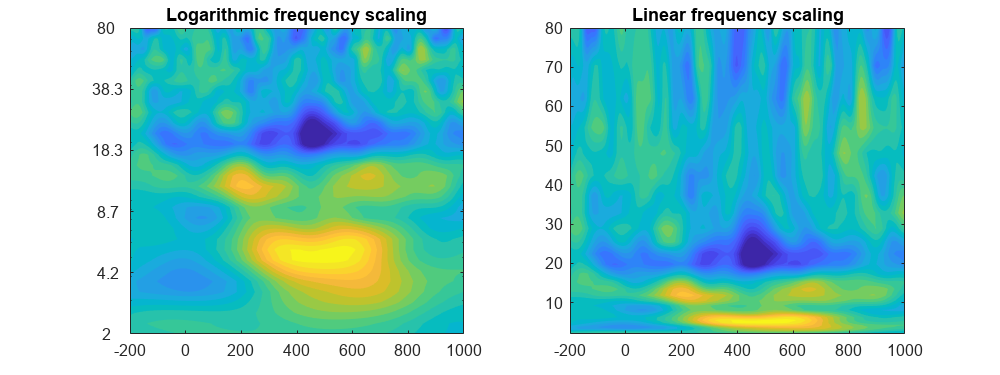

chan2use = 'fcz';
min_freq =  2;
max_freq = 80;
num_frex = 30;

time = -1:1/EEG.srate:1;
frex = logspace(log10(min_freq),log10(max_freq),num_frex);
s    = logspace(log10(3),log10(10),num_frex)./(2*pi*frex);

n_wavelet            = length(time);
n_data               = EEG.pnts*EEG.trials;
n_convolution        = n_wavelet+n_data-1;
n_conv_pow2          = pow2(nextpow2(n_convolution));
half_of_wavelet_size = (n_wavelet-1)/2;

eegfft = fft(reshape(EEG.data(strcmpi(chan2use,{EEG.chanlocs.labels}),:,:),1,EEG.pnts*EEG.trials),n_conv_pow2);

eegpower = zeros(num_frex,EEG.pnts);

baseidx = dsearchn(EEG.times',[-500 -200]');

for fi=1:num_frex
    wavelet = fft( sqrt(1/(s(fi)*sqrt(pi))) * exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*(s(fi)^2))) , n_conv_pow2 );
    
    eegconv = ifft(wavelet.*eegfft);
    eegconv = eegconv(1:n_convolution);
    eegconv = eegconv(half_of_wavelet_size+1:end-half_of_wavelet_size);
    
    temppower = mean(abs(reshape(eegconv,EEG.pnts,EEG.trials)).^2,2);
    eegpower(fi,:) = 10*log10(temppower./mean(temppower(baseidx(1):baseidx(2))));
end

figure(Position=[100,100,800,300])
subplot(121)
contourf(EEG.times,frex,eegpower,40,'linecolor','none')
set(gca,'clim',[-3 3],'xlim',[-200 1000],'yscale','log','ytick',logspace(log10(min_freq),log10(max_freq),6),'yticklabel',round(logspace(log10(min_freq),log10(max_freq),6)*10)/10)
title('Logarithmic frequency scaling')

subplot(122)
contourf(EEG.times,frex,eegpower,40,'linecolor','none')
set(gca,'clim',[-3 3],'xlim',[-200 1000])
title('Linear frequency scaling')

**Figure 13.12**

*Time-frequency results of the same analyses applied to the same data can look different depending on whether the frequencies in the y -axis are scaled logarithmically or linearly.*

### 13.7.5 How Long Should Wavelets Be?

Wavelets should be long enough such that the lowest-frequency wavelet tapers to zero at both the negative and positive ends of time. If the wavelet is cut off, edge artifacts will be present in the results. There is no limit on the maximum length of the wavelet because the wavelets taper to zero; multiplying the data by lots of zeros does not affect the result of wavelet convolution. Although wavelets at different frequencies may have different lengths, this will complicate your Matlab code and is not necessary. Unless you use wavelets with very low frequencies, defining wavelets using a time range of – 2 s to +2 s should be long enough.

A related and also important detail is that the wavelets should be centered in the time window. The center of the wavelet will thus be located at time = 0. This procedure has the added benefit that it will give the wavelet an odd number of data points, which is convenient for convolution. Finally, make sure the wavelet is created using the same sampling rate as the EEG data.

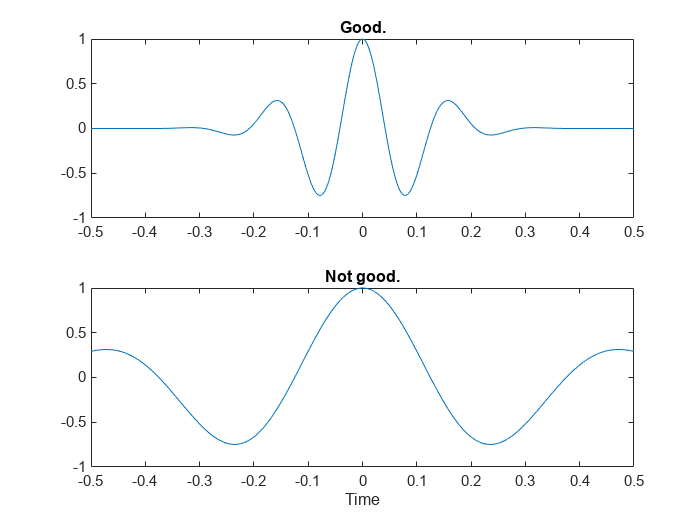

frequency = 6;
srate = 500;
time  = -.5:1/srate:.5;
wavelet = exp(2*1i*pi*frequency.*time) .* exp(-time.^2./(2*(4/(2*pi*frequency))^2));

figure
subplot(211)
plot(time,real(wavelet))
title('Good.')

tooLowFrequency = 2;
wavelet = exp(2*1i*pi*tooLowFrequency.*time) .* exp(-time.^2./(2*(4/(2*pi*tooLowFrequency))^2));

subplot(212)
plot(time,real(wavelet))
xlabel('Time')
title('Not good.')

**Figure 13.13**

*The lowest-frequency wavelet should taper cleanly to zeros. *

### 13.7.6 How Many Cycles Should Be Used for the Gaussian Taper?

The number of cycles of the Gaussian taper defines its width, which in turn defines the width of the wavelet. This parameter controls the trade-off between temporal and frequency precisions. This is sometimes called the trade-off between temporal and frequency resolution, but this is technically incorrect: both temporal resolution and frequency resolution are determined entirely by the data-sampling rate and do not change with analysis parameters; in contrast, it is their precisions that are affected by analysis parameters.

A larger number of cycles gives you better frequency precision at the cost of worse temporal precision, and a smaller number of cycles gives you better temporal precision at the cost of worse frequency precision. This is the parameter that controls the Heisenberg uncertainty principle applied to time-frequency analysis: the more you know about when something happened, the less you know about where (i.e., at which frequency) it happened, and vice versa.

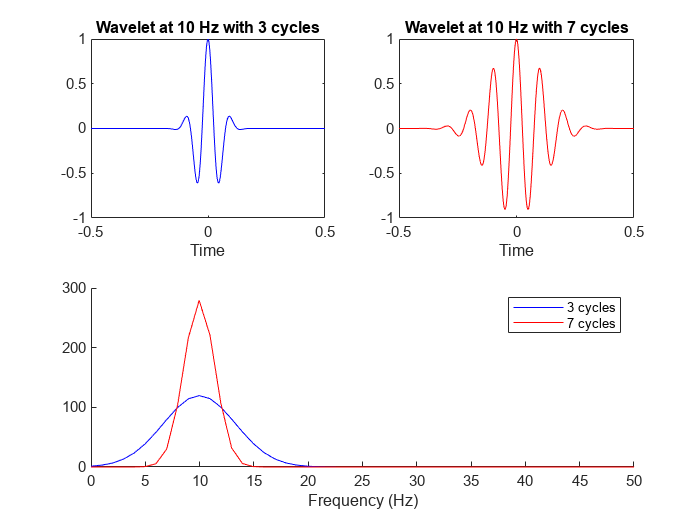

frequency = 10;
time      = -.5:1/srate:.5;
numcycles = [ 3 7 ];

wavecolors = 'br';

figure
for i=1:length(numcycles)
    wavelet = exp(2*1i*pi*frequency.*time) .* exp(-time.^2./(2*(numcycles(i)/(2*pi*frequency))^2));
    
    subplot(2,2,i)
    plot(time,real(wavelet),wavecolors(i))
    xlabel('Time')
    title([ 'Wavelet at ' num2str(frequency) ' Hz with ' num2str(numcycles(i)) ' cycles' ])
    
    subplot(2,1,2)
    hold on
    fft_wav = 2*abs(fft(wavelet));
    hz_wav  = linspace(0,srate/2,round(length(wavelet)/2)+1);
    plot(hz_wav,fft_wav(1:length(hz_wav)),wavecolors(i))
end

subplot(212)
xlabel('Frequency (Hz)')
set(gca,'xlim',[0 50])
legend({[ num2str(numcycles(1)) ' cycles' ];[ num2str(numcycles(2)) ' cycles' ]})

**Figure 13.14**

*Two wavelets at the same frequency that differ only in number of cycles have different temporal and frequency characteristics and therefore different sensitivities to temporal and frequency features of the data.*

A wavelet with few cycles has many more zero values compared to a wavelet with more cycles. This difference has several related implications:

- A shorter-cycle wavelet is better suited for detecting transient activations

- A longer-cycle wavelet is more sensitive to longer activations at specific frequencies

- A shorter-cycle wavelet is more precise at localizing dynamics in time

- A longer-cycle wavelet is more precise at determining the frequency of the dynamics. From the power-spectrum perspective of the two wavelets, although the peak frequencies are the same, their widths differ. In the extreme case of an infinite number of cycles, the wavelet becomes a sine wave, and wavelet convolution reduces to one step of the Fourier transform

The number of wavelet cycles you should use with real data depends on the goal of the analysis.

- If you are looking for transient changes in activity, a smaller number of cycles will be better

- If you have a relatively long trial period in which you expect frequency-band-specific activity, a larger number of cycles will facilitate identifying temporally sustained activity

- If you would like to distinguish activity at frequencies within a narrow range, you should use a larger number of cycles and accept the decreased temporal precision. 

- if you have hypotheses about how quickly a neural response can dissociate condition A from condition B, you should use a smaller number of cycles

- If both temporal precision and frequency precision are important for your study, you can perform the analysis twice

- If possible, the data should remain stationary during the period in which the wavelet is nonzero

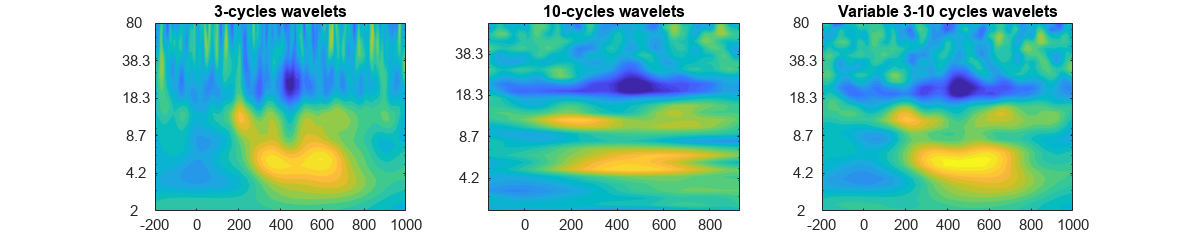

chan2use  = 'fcz';
min_freq  =  2;
max_freq  = 80;
num_frex  = 30;
min_cycle = 3;
max_cycle = 10;

time = -1:1/EEG.srate:1;
frex = logspace(log10(min_freq),log10(max_freq),num_frex);
cycles = [repmat([min_cycle;max_cycle],1,num_frex);logspace(log10(min_cycle),log10(max_cycle),num_frex)];

n_wavelet            = length(time);
n_data               = EEG.pnts*EEG.trials;
n_convolution        = n_wavelet+n_data-1;
n_conv_pow2          = pow2(nextpow2(n_convolution));
half_of_wavelet_size = (n_wavelet-1)/2;
n_cycle              = size(cycles, 1);

eegfft = fft(reshape(EEG.data(strcmpi(chan2use,{EEG.chanlocs.labels}),:,:),1,EEG.pnts*EEG.trials),n_conv_pow2);

eegpower = zeros(num_frex,EEG.pnts);

baseidx = dsearchn(EEG.times',[-500 -200]');

figure(Position=[100,100,1000,200])

for cy=1:n_cycle
    s = cycles(cy, :)./(2*pi*frex);
    for fi=1:num_frex
       
        wavelet = fft( sqrt(1/(s(fi)*sqrt(pi))) * exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*(s(fi)^2))) , n_conv_pow2 );
        
        eegconv = ifft(wavelet.*eegfft);
        eegconv = eegconv(1:n_convolution);
        eegconv = eegconv(half_of_wavelet_size+1:end-half_of_wavelet_size);
        
        temppower = mean(abs(reshape(eegconv,EEG.pnts,EEG.trials)).^2,2);
        eegpower(fi,:) = 10*log10(temppower./mean(temppower(baseidx(1):baseidx(2))));
    end
    
    subplot(1,n_cycle,cy)
    contourf(EEG.times,frex,eegpower,40,'linecolor','none')
    set(gca,'clim',[-3 3],'xlim',[-200 1000],'yscale','log','ytick',logspace(log10(min_freq),log10(max_freq),6),'yticklabel',round(logspace(log10(min_freq),log10(max_freq),6)*10)/10)
    if cy ~= 3
        title([num2str(cycles(cy, 1)) '-cycles wavelets'])
    end
end

title(['Variable ' num2str(min_cycle) '-' num2str(max_cycle) ' cycles wavelets'])

**Figure 13.15**

*The width of the Gaussian that is used to create the wavelets affects the features of the results that will be obtained from complex Morlet wavelet convolution. Different numbers of cycles can be used to highlight temporal precision or frequency precision.*

The number of wavelet cycles can also change as a function of frequency. This can be accomplished by increasing the number of cycles with the frequency of the wavelet. This is a useful procedure because it adjusts the balance between temporal and frequency precisions as a function of the frequency of the wavelet. It will also change the frequency spread of the wavelets as a function of frequency.

In general, you should use at least 3 cycles, and at most 14 cycles, unless you have a specific reason to do otherwise. If you use more than 7 cycles, it is a good idea to check that the wavelets taper to zero.

## 13.8 Determining the Frequency Smoothing of Wavelets

It might be relevant to know how much frequency smoothing the wavelets apply to your data. Because the wavelet has a Gaussian shape in the frequency domain , the extent to which neighboring frequencies contribute to the result of wavelet convolution can be reported in terms of full width at half-maximum (FWHM). FWHM refers to the frequency width for which the power is at 50% on the left and right sides of the peak (that is, the lower and upper 50% attenuation frequencies). The formula to compute the FWHM follows.

### 
$$\textrm{FWHM}=2\sqrt{2\textrm{ln2}}\sigma$$


- $\sigma$ is the standard deviation of the frequency response

- The constant $2\sqrt{2\mathrm{ln2}}$ is approximately $2\ldotp 36$

This formula is valid only for Gaussian distributions. In practice, it might be better to estimate the FWHM from the data rather than compute it algorithmically because the precise standard deviation will depend on the number of sample points, which in turn depends on the length of the wavelet and the sampling rate of the data:

- Normalize the power spectrum of the wavelet such that it has a minimum value of 0 and a maximum value of 1

- Identify the frequency points prior to and following the spectral peak that are closest to 0.5 

- Subtract those two frequencies

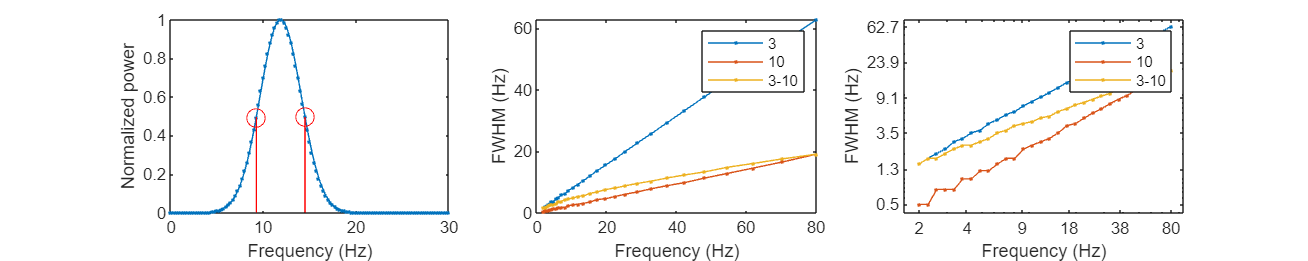

frex  = logspace(log10(2),log10(80),30);
srate = 500;
time  = -2:1/srate:2;
N     = length(time);
hz    = linspace(0,srate/2,floor(N/2)+1);
fwhm  = zeros(3,length(frex));

for numcyclesi = 1:3
    
    switch numcyclesi
        case 1
            numcycles=repmat(3,1,length(frex));
        case 2
            numcycles=repmat(10,1,length(frex));
        case 3
            numcycles=logspace(log10(3),log10(10),length(frex));
    end
    
    for fi=1:length(frex)
        
        wavelet = exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*(numcycles(fi)/(2*pi*frex(fi)))^2));
        
        fwave = fft(wavelet);
        fwave = abs(fwave(1:length(hz)))*2;
        
        fwave = fwave-min(fwave);
        fwave = fwave/max(fwave);
        
        [~,peakx]  = max(fwave);
        [~,left5]  = min(abs(fwave(1:peakx)-.5));
        [~,right5] = min(abs(fwave(peakx:end)-.5));
        right5 = right5+peakx-1;
        
        fwhm(numcyclesi,fi) = hz(right5)-hz(left5);
        
        if fi==ceil(length(frex)/2) && numcyclesi==3
            figure(Position=[100,100,1000,200])
            subplot(131)
            plot(hz,fwave,'.-')
            hold on
            
            plot(hz(left5),fwave(left5),'ro','markersize',10)
            plot(hz(right5),fwave(right5),'ro','markersize',10)
            plot([hz(left5) hz(left5)],[0 fwave(left5)],'r')
            plot([hz(right5) hz(right5)],[0 fwave(right5)],'r')            
            
            set(gca,'xlim',[0 30])
            xlabel('Frequency (Hz)')
            ylabel('Normalized power')
        end
    end
end

subplot(132)
plot(frex,fwhm,'.-')
xlabel('Frequency (Hz)')
ylabel('FWHM (Hz)')
legend({'3';'10';'3-10'})

subplot(133)
plot(frex,fwhm,'.-')
xlabel('Frequency (Hz)')
ylabel('FWHM (Hz)')
legend({'3';'10';'3-10'})
set(gca,'xlim',[frex(1)*.8 frex(end)*1.2],'ylim',[min(fwhm(:))*.8 max(fwhm(:))*1.2],'xscale','log','xtick',round(logspace(log10(frex(1)),log10(frex(end)),6)),'yscale','log','ytick',round(10*logspace(log10(min(fwhm(:))),log10(max(fwhm(:))),6))/10)

**Figure 13.15**

*FWHM of wavelets, shown for one wavelet, and for a family of wavelets.*

## 13.9 Tips for Writing Efficient Convolution Code in Matlab

Because the Fourier transform of the EEG data does not change as a function of frequency, the FFT of the data needs to be computed only once before looping over frequencies. In contrast, if you use the Matlab conv function, the FFT of the data will be redundantly recomputed at each iteration inside the frequency loop.

You can further decrease analysis time by using FFTs of an order that is a power of two. Usually, data time series must be zero-padded to get to a length that is a power of two. The online Matlab code for this chapter shows you how to zero-pad FFTs and then remove the extra points after convolution. 

Finally, you do not need to perform convolution on each trial separately; it is faster and more elegant to concatenate all trials into one long time series, perform one convolution with all trials, and then reshape the result back to a time-by-trials matrix.

## 13.10 Describing This Analysis in Your Methods Section

If you perform a complex Morlet wavelet convolution to analyze your data, there are several important details to include in the Methods section, including: 

- The minimum, maximum, and number of frequencies of the wavelets

- Whether frequencies increased linearly or logarithmically

- The number of wavelet cycles and whether this changed as a function of frequency

Morlet wavelets are commonly used in the literature, so it is not necessary to include the equations in the Methods section unless you modify the standard equations. On the other hand, the equations for Morlet wavelets are brief, so there is little concern about exceeding journal space or word count limitations. You could also report the frequency domain FWHM of the wavelets, although this is not typically done.